# Exercise 1: A Simple Blade

Prof. Dr.-Ing. Jens Geisler, last update 3 July 2025

## Preamble

Let's start with a clean workspace and set up the required path. Make sure you are in the examples folder of the CADynM Project!

**This exercise it divided into several sections. Use ****Strg+Enter**** / Ctrl+Enter to run individial sections and avoid unnecessary computation of the others.**

addpath('../toolbox')
clear

## Modeling

Every multibody model starts with a system object to store the state, input and parameter variables and to serve as the inertial coordinatessystem.

one_blade= MultiBodySystem('One Blade');

% the one and only generalized coordinate, the blade flap-wise
% bending DOF
one_blade.addGeneralizedCoordinate('e_b1')

% the modal force to act on the blade
one_blade.addInput('Fb1')

% the only parameter in this system, the gravitational constant
one_blade.addParameter('g');
% it needs to be set to the systems gravity vector.
% (wherever parameters are used, constant numbers could also be used)
one_blade.gravity(1) = one_blade.params.g; % X-direction (the blade will extend in the positive Z-direction)

Now, let's create the blade elastic body.

% the SID for the blade are precomputed and storedin a file
load('blade_sid')
% arguments: vector of elastic DOF, SID struct, optional name
blade= ElasticBody(one_blade.dof.e_b1, bd_sid, 'blade');

FInally, we add the blade to the system (attach it to the inertial reference), and apply the force input to the blade.

one_blade.addChild(blade)
one_blade.applyElasticForce(one_blade.inputs.Fb1, blade)

## Create EOM

To create the equations of motion, we first need to let the system prepare the kinematics. Then we choose to generate an implicit first order ode function that is stored in the appointed file. 

one_blade.completeSetup()
one_blade.eomDae('OneBlade_DAE.m')

**TASK01:** Open the generated ODE function and inspect its contents. The second order ode has been transformed into a first order ode. Each DOF has two states: one position state `x1_1` and one velocity state `x2_1`. Each state has a derivative `YP1` resp. `YP2`. The first row of the ode relates the derivative of the position-state to the velocity state. The second row ist the real equation of motion.

**TASK02:** What is the modal stiffness of the blade, what is its modal mass?

## Simulation

For the simulation, we first need to set the parameter values in a struct with names according to the ones we declared in the system. Then we need to transform these parameters into a vector.

p.g = 0;
params= one_blade.paramVec(p);

The input force, we defined for the blade, needs to be define as a function (here a local function). For now, let's assume no force.

blade_force= @(t)0;

For the simulation, the ode-function needs to be wrapped into a so-called lambda to set the input functions and parameters.

F = @(t,Y,YP) OneBlade_DAE(t, Y, YP, [blade_force(t)], [], params);

Now, let's configure the simulation run time, the initial states and the solver options and run the simulation. The simulations shall start with the blade being deflected by one (meter at the tip). The derivative of the initial state, `dx0`, is only a guess that we set consistent with the state. 

t_end= 50;

x0 = [1 0]';
dx0= [x0(one_blade.getNumDOF+1:end)' 0*x0(one_blade.getNumDOF+1:end)']';

opt= odeset(AbsTol=1e-5, RelTol=1e-3);

sim_res= ode15i(F, [0,t_end], x0, dx0, opt);

Finally, to visualize the solution, we plot the deflection state. We can use `one_blade.dof_idx` to comfortably index the desired state in the solution matrix returned by the solver.

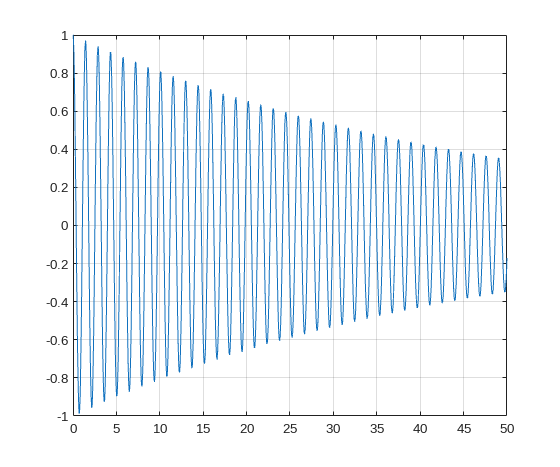

plot(sim_res.x, sim_res.y(one_blade.dof_idx.e_b1, :))
grid on

**TASK03:** Change the gravitational constant parameter value to 9.81, set the initial deflection of the blade to 0 and rerun the simulation.

**EXTRA04:** Change the direction of gravity to the Y-direction, rebuild the model and simulate again. In which direction does the blade bend more?

**EXTRA05:** Set gravity back to 0 and apply some non-zeroblade force function, e.g. a sin-wave with a certain frequency.

## Analysis

Now, let's analyse the eigenfrequency of the blade. We rerun a simulation with an initial blade defelection.

blade_force= @(t)0;
F = @(t,Y,YP) OneBlade_DAE(t, Y, YP, [blade_force(t)], [], params);
t_end= 50;

x0 = [1 0]';
dx0= [x0(one_blade.getNumDOF+1:end)' 0*x0(one_blade.getNumDOF+1:end)']';

opt= odeset(AbsTol=1e-5, RelTol=1e-3);

sim_res= ode15i(F, [0,t_end], x0, dx0, opt);

Then, we resample the data to a uniform sampling time.

dt= 0.02;
e_b1_sim = interp1(sim_res.x, sim_res.y(one_blade.dof_idx.e_b1, :), 0:dt:t_end);

and view the power spectral density (psd):

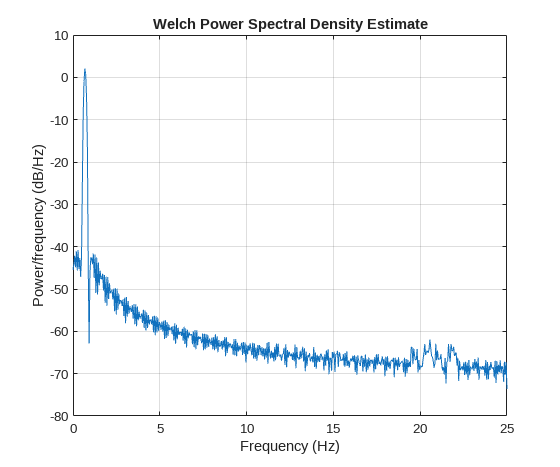

pwelch(e_b1_sim, [], [], [], 1/dt);

**TASK06:** Use a data tip in the plot of the power spectral density to identify the blade eigenfrequency.

From the power spectral density, we can automatically extract the peak, which is the eigenfrequency.

[pxx, f]=pwelch(e_b1_sim, [], [], [], 1/dt);
[~, ef] = findpeaks(10*log10(pxx), f, 'NPeaks', 1, 'SortStr', 'descend')

ef = 0.6836

**TASK07: **Compare the automatically computed value with your reading.

**EXTRA08:** How does the eigenfrequency from the psd compare to the theoretic value from the blade modal mass and stiffness identified in TASK02?

**EXTRA09:** Change the direction of gravity to the Z-direction and recreate the model. Set the parameter for gravity to a high value (e.g. 100). How does the eigenfrequeny change, and why? How does it change, when you set a negative gravity? 